# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Ploting Parameters

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

## Data Transmission Parameters

Parameters related to the data transmission, e.g., number of bits, constellation size, number of subcarriers, and number of transmitted blocks.

B     = [1 2 3 4 5 6];                 % Number of bits in a symbol
Q     = 2.^B;                          % Constellation size
N_B   = length(B);                     % Length of B
N_BLK = 20000;                         % Number of transmitted data blocks

## Environment Parameters

Parameters related to the environment noise.

SNR   = -5:20;                         % Signal-to-noise ratio in dB
N_SNR = length(SNR);                   % Length of SNR

# Communication System

y   = zeros(N_BLK,N_B,N_SNR);
BER = zeros(N_SNR,N_B);

## Transmitter

for n = 1:N_B
    m_bit = randi([0 1],B(n)*N_BLK,1);
    m_mod = qammod(m_bit,Q(n),'InputType','bit');                  % Q-QAM modulation
    x = m_mod;

    Px = norm(x)^2/length(x);                                      % Average transmission power

## Receiver

    for snr_ind = 1:N_SNR    
        v  = (randn(length(x),1) + 1i*randn(length(x),1))/sqrt(2); % AWGN noise
        Pv = norm(v)^2/length(v);                                  % Average noise power
    
        v  = sqrt(((Px/Pv))*(10^(-SNR(snr_ind)/10)))*v;            % True AWGN noise
    
        y(:,n,snr_ind) = x + v;                                    % Received signal
    
        m_bit_hat = qamdemod(y(:,n,snr_ind),Q(n),'OutputType','bit');
        m_bit_hat = m_bit_hat(1:B(n)*N_BLK);
    
        BER(snr_ind,n) = sum(sum(abs(m_bit(:)-m_bit_hat(:))))/length(m_bit_hat(:));
    end
end

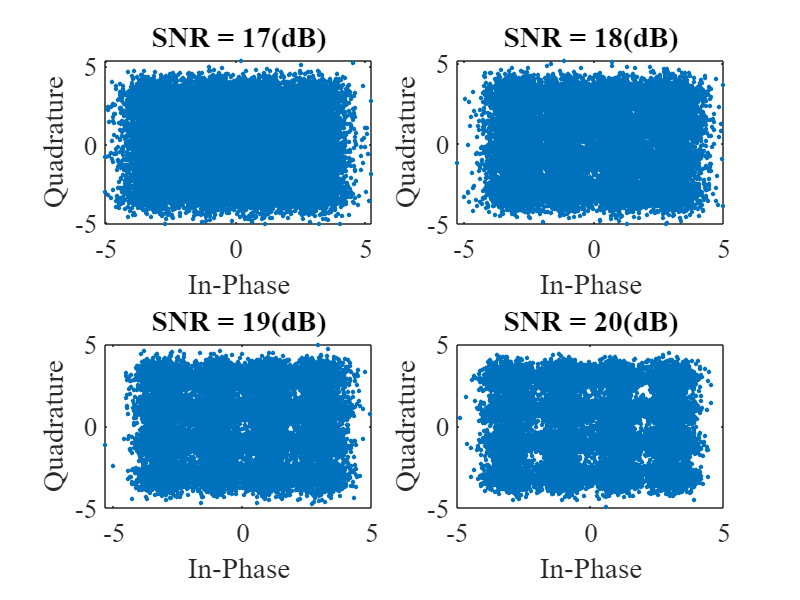

B_plt_idx    = 4;
SNR_plot_idx = [17 18 19 20];

figure;

set(gcf,'position',[0 0 800 600]);

for plt_idx = 1:4

    subplot(2,2,plt_idx)

    plot(real(y(:,B_plt_idx,SNR_plot_idx(plt_idx))),imag(y(:,B_plt_idx,SNR_plot_idx(plt_idx))),'.','markersize',markersize);

    title(['SNR = ' num2str(SNR_plot_idx(plt_idx)) '(dB)'],'fontname',fontname,'fontsize',fontsize);
    xlabel('In-Phase','fontname',fontname,'fontsize',fontsize);
    ylabel('Quadrature','fontname',fontname,'fontsize',fontsize);

    set(gca,'fontname',fontname,'fontsize',fontsize);

end

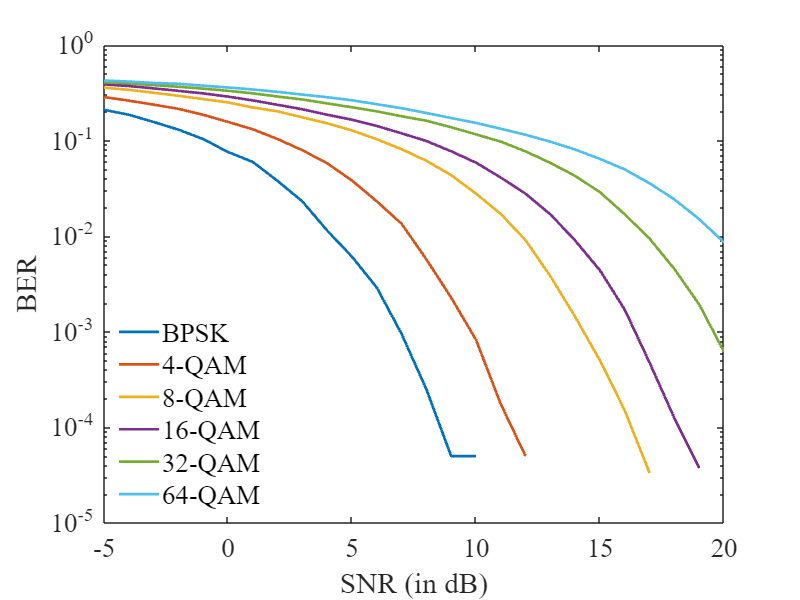

figure;

set(gcf,'position',[0 0 800 600]);

semilogy(SNR,BER(:,1),'linewidth',linewidth);
hold on;
semilogy(SNR,BER(:,2),'linewidth',linewidth);
semilogy(SNR,BER(:,3),'linewidth',linewidth);
semilogy(SNR,BER(:,4),'linewidth',linewidth);
semilogy(SNR,BER(:,5),'linewidth',linewidth);
semilogy(SNR,BER(:,6),'linewidth',linewidth);

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

legend({'BPSK','4-QAM','8-QAM','16-QAM','32-QAM','64-QAM'},'fontname',fontname,'fontsize',fontsize,'location','southwest')
legend box off

set(gca,'fontname',fontname,'fontsize',fontsize);